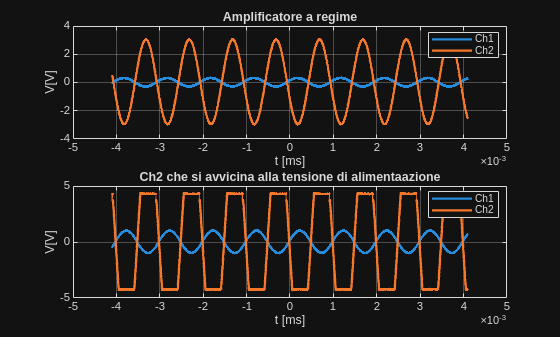

cd(fileparts(matlab.desktop.editor.getActiveFilename));

tbl1 = readtable("dati/acquisizione01.txt", NumHeaderLines=3);
tbl1.Properties.VariableNames = ["t", "Ch1", "Ch2"];

tbl2 = readtable("dati/acquisizione02.txt", NumHeaderLines=3);
tbl2.Properties.VariableNames = ["t", "Ch1", "Ch2"];

% --- Subplot 1: modulo ---
subplot(2,1,1)
plot(tbl1.t, tbl1.Ch1, 'LineWidth', 1.8)
hold on
plot(tbl1.t, tbl1.Ch2, 'LineWidth', 1.8)
hold off
xlabel('t [ms]')
ylabel('V[V]')
legend("Ch1", "Ch2", 'Location', 'best')
title('Amplificatore a regime')
grid on

% --- Subplot 2: fase ---
subplot(2,1,2)
plot(tbl2.t, tbl2.Ch1, 'LineWidth', 1.8)
hold on
plot(tbl2.t, tbl2.Ch2, 'LineWidth', 1.8)
hold off
xlabel('t [ms]')
ylabel('V[V]')
legend("Ch1", "Ch2", 'Location', 'best')
title('Ch2 che si avvicina alla tensione di alimentaazione')
grid on

% --- Esporta la figura ---
exportgraphics(gcf, "grafici/AmplificatoreInvertente.pdf", ContentType = "vector");